# **IO751 & IO752 - PROFINET Record**

The IO751 and IO752 are PROFINET I/O modules that are used to connect real-time target machines to industrial equipment. The IO751 is a PROFINET Controller module that is used to communicate with field-level devices such as motor controllers and sensors. The IO752 is a PROFINET Device module that is used to communicate with devices on the control and process level such as programmable logic controllers. The modules handle the complete data exchange between the real-time application and the connected devices. The data exchange is processed via a dual-port memory. Each module acts as one PROFINET station exclusively. The two Ethernet connectors enable easy network integration.

PROFINET communication typically takes place between one PROFINET Controller and multiple PROFINET Devices. In this example, one controller (IO751) communicates with one device (IO752) installed in the same target machine. PROFINET supports cyclic and acyclic communication. While the cyclic communication with data modules and sub-modules is illustrated by the IO751 & IO752 Loopback example, this example covers acyclic communication with records. A PROFINET Record is a data item in the memory of the PROFINET Device, that can be read and written by the remote PROFINET Controller. This kind of communication usually takes place right after the controller finds the device in the network. The controller writes parameters and reads configuration values. Subsequently, the reading and writing of records is triggered by events or, in rare cases, happens periodically with low updates rates. Acyclic communication has basically a lower priority than cyclic communication. This applies to the data exchange on the network as well as the message handling inside the PROFINET Controller and Device applications.

The IO751 and IO752 modules are configured to exchange generic values. The IO751 is periodically triggered to send and read records with a lower rate than the base sample time of the model. The IO752 updates its local records with the same rate.

The IO751 module requires a configuration file (included with this example). The file is created with SYCON.net, a software tool from Hilscher. The IO752 is completely configured in Simulink.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO751 and one IO752 installed

- CAT5 Ethernet cable or newer

The IO751 module requires a configuration file. This file comes with the example model and does not have to be created. However, the SYCON.net project is also included in the example and can be used to recreate the configuration file. The module help documentation and the SYCON documentation explain how to use SYCON.net, which is free of charge.

### Pin Mapping/Connection Diagram/Test Setup

PROFINET is an Ethernet-based protocol. Use a CAT5 cable or newer to connect the IO751 with the IO752. Both modules have 2 connectors. It does not matter which one you use.

The configuration file (*.nxd) must be located on the target machine. The PROFINET Loopback and Record examples share the same config file and SYCON.net project for the PROFINET controller.

## Initialize and Open the Simulink model

 
% Sample time
Ts_base = 0.001;
Ts_record = 0.01;

% Open Simulink model
modelName = 'sgMdl_IO751_IO752_PROFINETRecord';
open_system(modelName);

% Sample time
set_param(modelName, 'StopTime', '10');

## Model Description

The model sets up the communication for both the IO751 and IO752. When starting the model, the [IO751 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io751_setup_v2) block loads the corresponding configuration file onto the I/O module. The [IO752 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io752_setup_v3) blocks set up the cyclic communication based on the modules and sub-modules configured:

- one 12-byte input module in slot 1 sub-slot 1

- one 16-byte output module in slot 2 sub-slot 1

The [IO752 Record](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io752_record) blocks add the following records to the local record list inside the I/O module:

- one record of data type uint32 on index 1 in slot 1 sub-slot 1

- one record of data type double on index 2 in slot 1 sub-slot 3

Records can only be added to slots and sub-slots that are defined by the module and sub-module configuration in the [IO752 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io752_setup_v3) block. One sub-slot can manage up to 256 record indices.

The IO751 Record Read and Write blocks are used to exchange data with the remote device's records:

- the [IO751 Record Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io751_record_write) block writes a 32-bit counter signal to the first record in the IO752

- the [IO751 Record Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io751_record_read) block reads the 64-bit sine wave from the second record in the IO752. This signal is logged and output to the scope

The [IO752 Record](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io752_record) blocks are used to update the local records:

- the IO752 Record block representing the first record, outputs the 32-bit counter signal written by the IO751. This signal is logged and output to the scope

- the IO752 Record block representing the second record, writes a 64-bit sine wave which is read by the IO751

The IO751 and IO752 Send and Receive blocks are actually used for cyclic communication only but basically enable acyclic communication as well. They are required in the example model and must exchange at least 1 byte. Besides that, they serve no further purpose.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Prepare the Simulink Data Inspector to plot signals
Simulink.sdi.clearAllSubPlots;
Simulink.sdi.setSubPlotLayout(2,2);
Simulink.sdi.view;

% Start the real-time application
tg.start;

% Select the signals for plotting, set the axis limits and line colors
sdiRunIDs = Simulink.sdi.getAllRunIDs;
sdiLatestRun = Simulink.sdi.Run.getLatest;
s = sdiLatestRun.getSignalsByName('Sine');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('Counter');
plotOnSubPlot(s,1,2,true);
s = sdiLatestRun.getSignalsByName('Sine_Status');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('Counter_Status');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('Sine_Length');
plotOnSubPlot(s,2,2,true);
s = sdiLatestRun.getSignalsByName('Counter_Length');
plotOnSubPlot(s,2,2,true);

Simulink.sdi.setSubplotLimits(1,1,'AllRange',[0,10,-11,11]);
Simulink.sdi.setSubplotLimits(1,2,'AllRange',[0,10,-100,10100]);
Simulink.sdi.setSubplotLimits(2,1,'AllRange',[0,10,-10,1010]);
Simulink.sdi.setSubplotLimits(2,2,'AllRange',[0,10,-1,11]);

## Check the Results

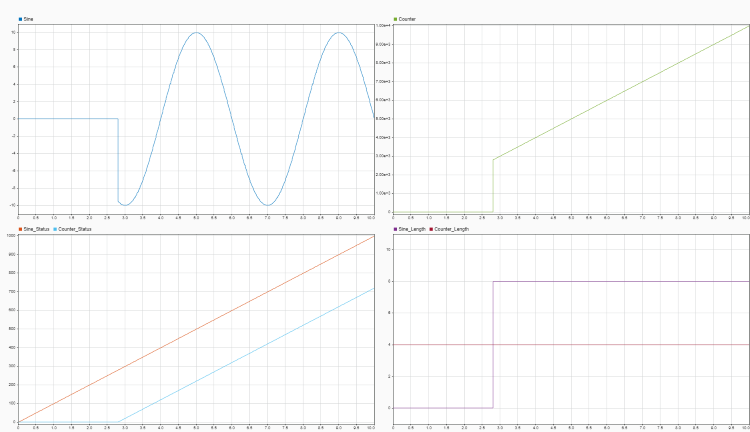

## Additional References

- [IO751 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io751)

- [IO752 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io752)